# Aula_04_ECM307 - Propriedades da Série exponencial de Fourier

Felipe Fazio da Costa; RA: 23.00055-4

## Boas práticas

% Limpando todo sistema para início dos calculos
clear;
close all;
clc;

## Função de análise(1):

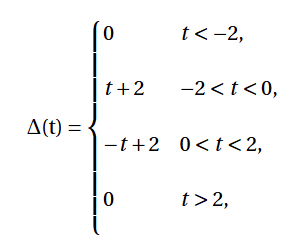

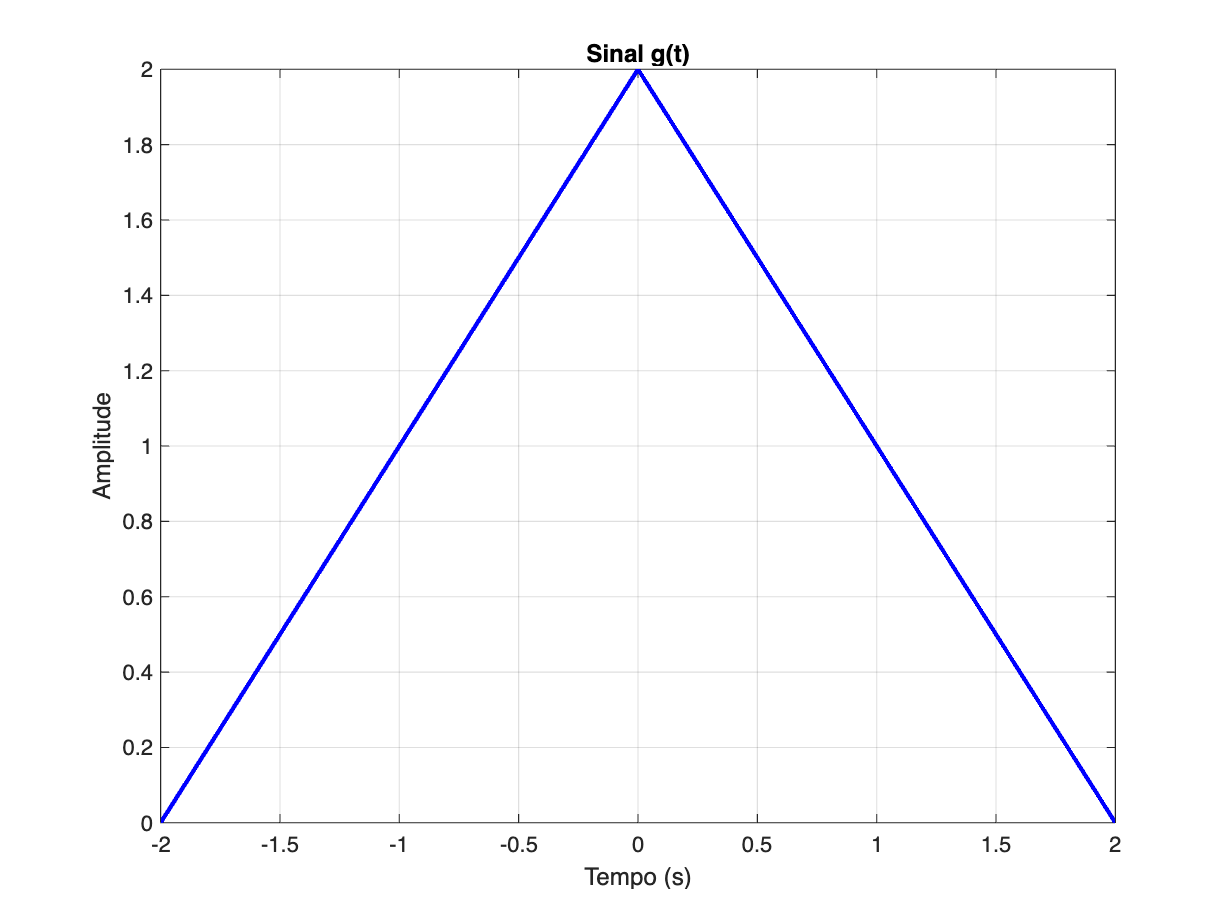

% Numericamente o primeiro período:
t1 = -2 : 1e-3 : 0;
g1 = t1+2;

% Numericamente o segundo período:
t2 = 0 : 1e-3 : 2;
g2 = -t2+2;

% Numericamente 3 períodos:
t = -2 : 1e-3 : 2;
plot(t, [g1 g2(2:end)], 'b', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinal g(t)');
grid on;

## Calculando Dn

% Declaração de variáveis:
syms n t;

To = 4;
t0 = -2;
tf = 2;
w0 = 2 * pi/ To;

% Dn simbólico
Dn = (1/To) * (int((t+2) * exp(-1 * 1i * n * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * n * w0 * t), t, 0, tf))

$$Dn = \frac{1}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}$$

D0 = (1/To) * (int((t+2) * exp(-1 * 1i * 0 * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * 0 * w0 * t), t, 0, tf))

$$D0 = 1$$

## Calculando Pg

% Declaração de variáveis:
syms n t;

To = 4;
t0 = -2;
tf = 2;
w0 = 2 * pi/ To;

% Pg simbólico
Pg = 1/To * (int((t+2)^2,  t, t0, 0) + int((t+2)^2,  t, t0, 0))

$$Pg = \frac{4}{3}$$

## Valor numérico de Dn

% Número de Dn´s

Ni = -20;
Nf = 20;
n = Ni:1:Nf;

num_dn = eval(Dn)

num_dn =    0.0000 + 0.0000i   0.0011 + 0.0000i   0.0000 + 0.0000i   0.0014 - 0.0000i   0.0000 + 0.0000i   0.0018 + 0.0000i   0.0000 + 0.0000i   0.0024 - 0.0000i   0.0000 + 0.0000i   0.0033 + 0.0000i   0.0000 + 0.0000i   0.0050 + 0.0000i   0.0000 + 0.0000i   0.0083 - 0.0000i   0.0000 + 0.0000i   0.0162 - 0.0000i   0.0000 + 0.0000i   0.0450 + 0.0000i   0.0000 + 0.0000i   0.4053 - 0.0000i      NaN -    Infi   0.4053 + 0.0000i   0.0000 - 0.0000i   0.0450 - 0.0000i   0.0000 - 0.0000i   0.0162 + 0.0000i   0.0000 - 0.0000i   0.0083 + 0.0000i   0.0000 - 0.0000i   0.0050 - 0.0000i   0.0000 - 0.0000i   0.0033 - 0.0000i   0.0000 - 0.0000i   0.0024 + 0.0000i   0.0000 - 0.0000i   0.0018 - 0.0000i   0.0000 - 0.0000i   0.0014 + 0.0000i   0.0000 - 0.0000i   0.0011 - 0.0000i   0.0000 - 0.0000i


% Substituindo o not a number, sabendo o D0:
num_dn(21) = 1;

## Síntese da função

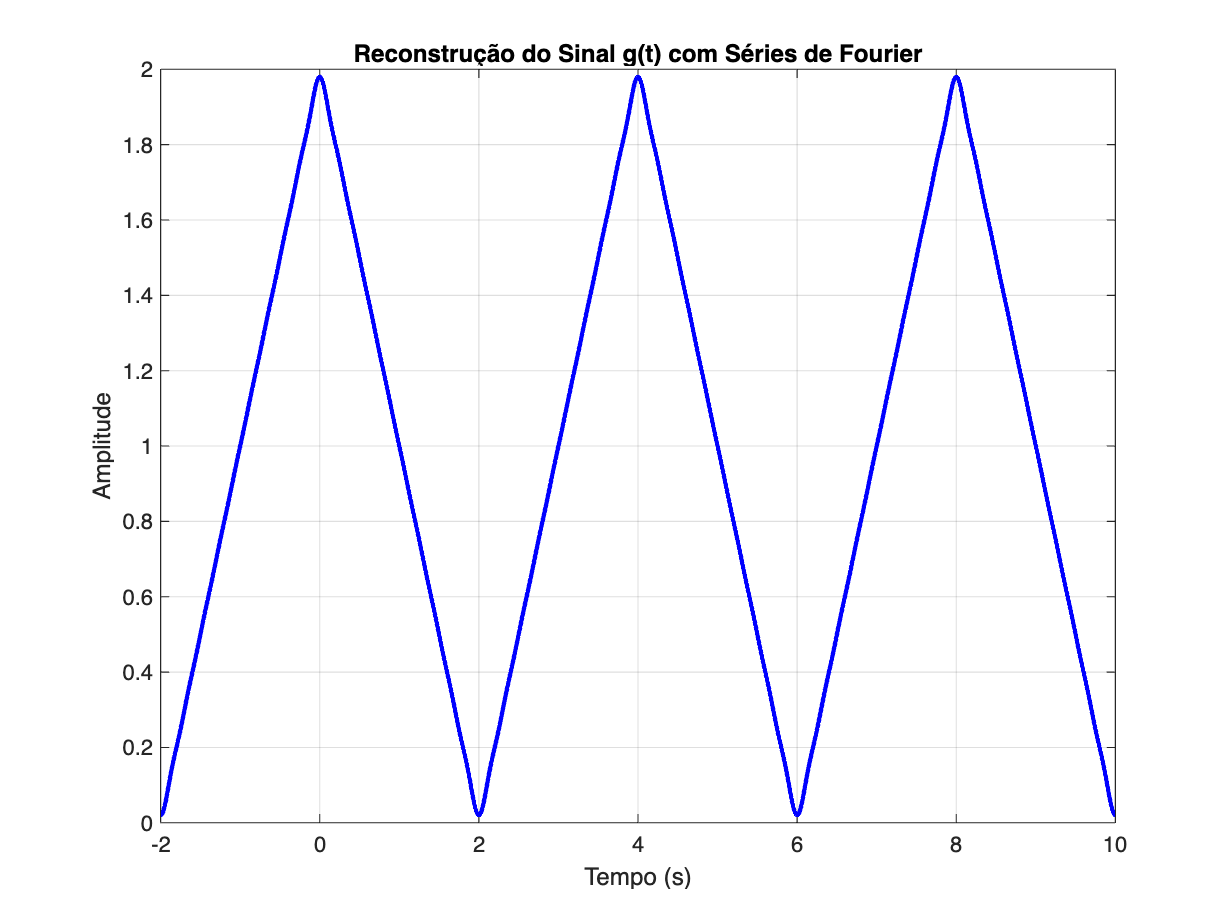

% Declarando o número de Harmônicas:
Ni = -20;
Nf = 20;
n = Ni:1:Nf;

w0 = 2 * pi/ To;
To = 4;

tempo = -2 : 1e-3 : 10;  % Define o vetor tempo

% Inicializando o sinal sintetizado
aux = 0;

% Realizando a soma da Série de Fourier
for k = 1:41  % Agora usamos o índice k para acessar os valores de n

    aux = aux + num_dn(k) * exp(1i * n(k) * w0 * tempo);  % Soma a harmônica ao sinal

end

% Plotando o sinal reconstruído
figure;
plot(tempo, real(aux), 'b', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Reconstrução do Sinal g(t) com Séries de Fourier');
grid on;

## Boas práticas

% Limpando todo sistema para início dos calculos
clear;
close all;
clc;

## Função de análise(2):

## Calculo de Dn1


% Declaração de variáveis:
syms n t;

To = 8;
t0 = -2;
tf = 2;
w0 = 2 * pi/ To;

% Dn simbólico
Dn = (1/To) * (int((t+2) * exp(-1 * 1i * n * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * n * w0 * t), t, 0, tf))

$$Dn = \frac{2}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{2-2\,{\mathrm{e}}^{\frac{\pi \,n\,\mathrm{i}}{2}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{2\,{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}}{n^{2}\,\pi^{2}}$$

## Agora para a função g1(t)

% Fazendo o ajuste

% Declaração de variáveis
to = 2;
to2 = 6;

To = 8;
w0 = 2 * pi/ To;

Dn1 = Dn * exp(-1 * 1i * n * w0 * to)

$$Dn1 = -{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}\,\left(\frac{\mathrm{i}}{n\,\pi }-\frac{2}{n^{2}\,\pi^{2}}-\frac{2-2\,{\mathrm{e}}^{\frac{\pi \,n\,\mathrm{i}}{2}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}+\frac{2\,{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}}{n^{2}\,\pi^{2}}\right)$$

Dn2 = Dn * exp(-1 * 1i * n * w0 * to2)

$$Dn2 = -{\mathrm{e}}^{-\frac{3\,\pi \,n\,\mathrm{i}}{2}}\,\left(\frac{\mathrm{i}}{n\,\pi }-\frac{2}{n^{2}\,\pi^{2}}-\frac{2-2\,{\mathrm{e}}^{\frac{\pi \,n\,\mathrm{i}}{2}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}+\frac{2\,{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}}{n^{2}\,\pi^{2}}\right)$$

## Calculando Dn0

% Declaração de variáveis:
syms t;

To = 8;
w0 = 2 * pi/ To;
to = -2;
to2 = -6;

t0 = -2;
tf = 2;

D0 = (1/To) * (int((t+2) * exp(-1 * 1i * 0 * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * 0 * w0 * t), t, 0, tf))

$$D0 = \frac{1}{2}$$


Dn0_1 = D0 * exp(-1 * 1i * 0 * w0 * to)

$$Dn0\_1 = \frac{1}{2}$$

Dn0_2 = D0 * exp(-1 * 1i * 0 * w0 * to2)

$$Dn0\_2 = \frac{1}{2}$$

## Calculando Pg1

% Declaração de variáveis:
syms n t;

To = 8;
t0 = -2;
tf = 2;
w0 = 2 * pi/ To;

% Pg simbólico
Pg1 = 1/To * int((t-2)^2,  t, t0, 0);
Pg2 = 1/To * int((t-4)^2,  t, 0, tf);

% Pg total:
Pgt = Pg1 - Pg2

$$Pgt = 0$$

## Valor numérico de Dn1

% Número de Dn´s

Ni = -20;
Nf = 20;
n = Ni:1:Nf;

num_dn1 = eval(Dn1)

num_dn1 =    0.0000 + 0.0000i  -0.0000 - 0.0011i  -0.0025 - 0.0000i  -0.0000 + 0.0014i   0.0000 + 0.0000i  -0.0000 - 0.0018i  -0.0041 + 0.0000i   0.0000 + 0.0024i   0.0000 + 0.0000i   0.0000 - 0.0033i  -0.0081 + 0.0000i  -0.0000 + 0.0050i   0.0000 + 0.0000i  -0.0000 - 0.0083i  -0.0225 + 0.0000i   0.0000 + 0.0162i   0.0000 + 0.0000i   0.0000 - 0.0450i  -0.2026 + 0.0000i   0.0000 + 0.4053i      NaN +    NaNi   0.0000 - 0.4053i  -0.2026 - 0.0000i   0.0000 + 0.0450i   0.0000 - 0.0000i   0.0000 - 0.0162i  -0.0225 - 0.0000i  -0.0000 + 0.0083i   0.0000 - 0.0000i  -0.0000 - 0.0050i  -0.0081 - 0.0000i   0.0000 + 0.0033i   0.0000 - 0.0000i   0.0000 - 0.0024i  -0.0041 - 0.0000i  -0.0000 + 0.0018i   0.0000 - 0.0000i  -0.0000 - 0.0014i  -0.0025 + 0.0000i  -0.0000 + 0.0011i   0.0000 - 0.0000i


num_dn2 = eval(Dn2)

num_dn2 =    0.0000 + 0.0000i   0.0000 + 0.0011i  -0.0025 + 0.0000i   0.0000 - 0.0014i   0.0000 + 0.0000i   0.0000 + 0.0018i  -0.0041 - 0.0000i   0.0000 - 0.0024i   0.0000 + 0.0000i   0.0000 + 0.0033i  -0.0081 + 0.0000i  -0.0000 - 0.0050i   0.0000 + 0.0000i  -0.0000 + 0.0083i  -0.0225 + 0.0000i  -0.0000 - 0.0162i   0.0000 + 0.0000i   0.0000 + 0.0450i  -0.2026 + 0.0000i  -0.0000 - 0.4053i      NaN +    NaNi  -0.0000 + 0.4053i  -0.2026 - 0.0000i   0.0000 - 0.0450i   0.0000 - 0.0000i  -0.0000 + 0.0162i  -0.0225 - 0.0000i  -0.0000 - 0.0083i   0.0000 - 0.0000i  -0.0000 + 0.0050i  -0.0081 - 0.0000i   0.0000 - 0.0033i   0.0000 - 0.0000i   0.0000 + 0.0024i  -0.0041 + 0.0000i   0.0000 - 0.0018i   0.0000 - 0.0000i   0.0000 + 0.0014i  -0.0025 - 0.0000i   0.0000 - 0.0011i   0.0000 - 0.0000i



% Substituindo o not a number, sabendo o D0:
num_dn1(21) = Dn0_1;
num_dn2(21) = Dn0_2;

## Síntese da função

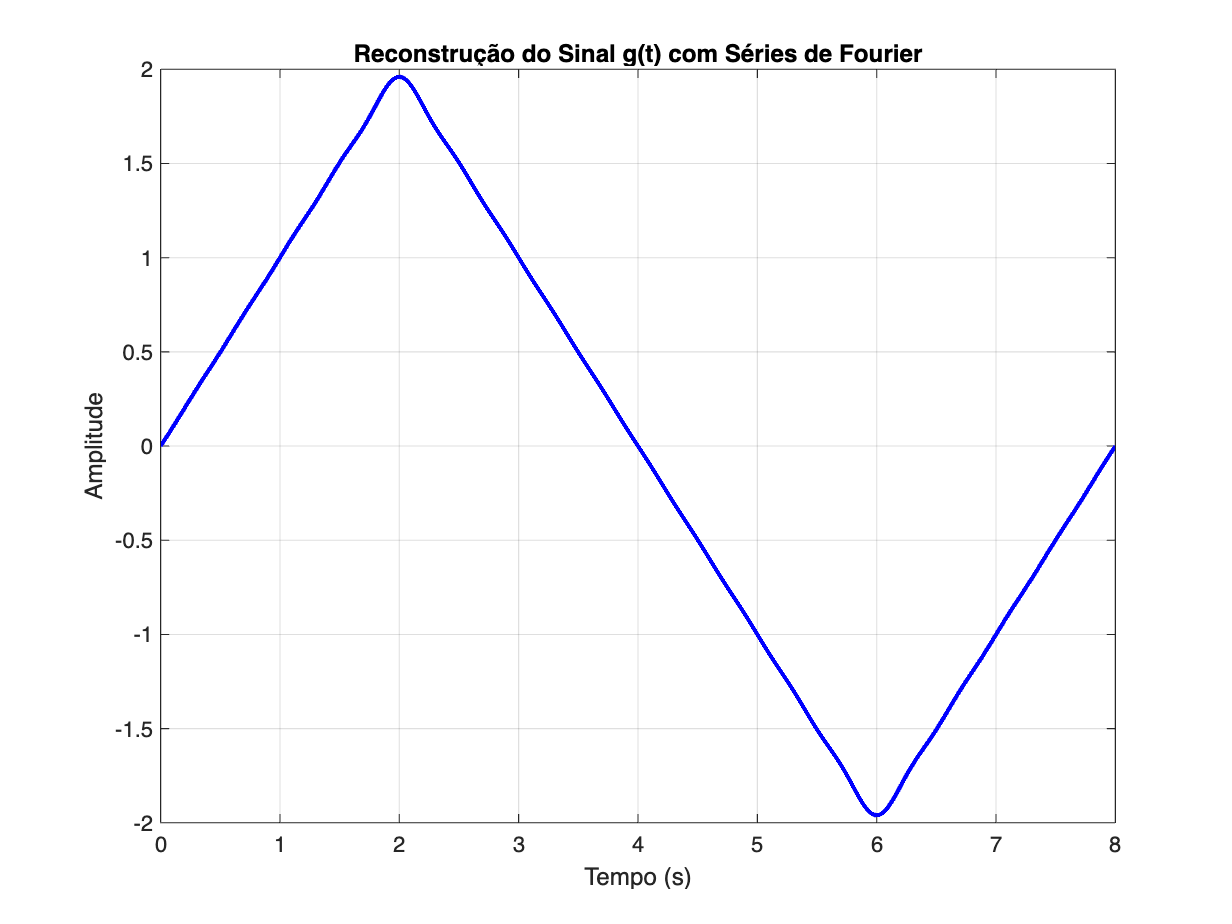

% Declarando o número de Harmônicas:
Ni = -20;
Nf = 20;
n = Ni:1:Nf;

To = 8;
w0 = 2 * pi/ To;


tempo = 0 : 1e-3 : 8;  % Define o vetor tempo

% Inicializando o sinal sintetizado
aux = 0;

% Realizando a soma da Série de Fourier
for k = 1:41  % Agora usamos o índice k para acessar os valores de n

    aux = aux + num_dn1(k) * exp(1i * n(k) * w0 * tempo);  % Soma a harmônica ao sinal
    aux = aux - num_dn2(k) * exp(1i * n(k) * w0 * tempo);  % Soma a harmônica ao sinal

end

% Plotando o sinal reconstruído
Dn_sintetizado = aux;
figure;
plot(tempo, real(Dn_sintetizado), 'b', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Reconstrução do Sinal g(t) com Séries de Fourier');
grid on;

## Função de análise(1):

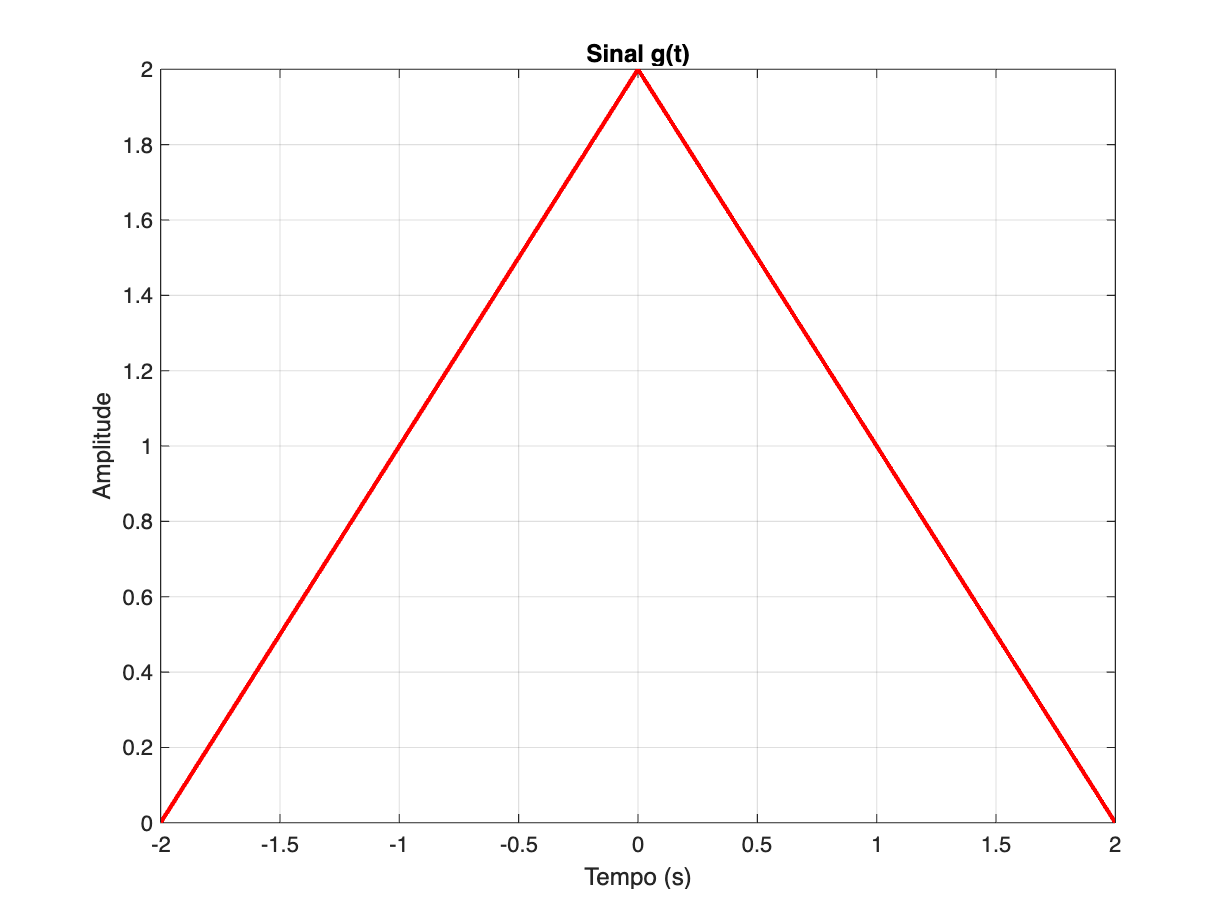

% Numericamente o primeiro período:
t1 = -2 : 1e-3 : 0;
g1 = t1+2;

% Numericamente o segundo período:
t2 = 0 : 1e-3 : 2;
g2 = -t2+2;

% Numericamente 3 períodos:
t = -2 : 1e-3 : 2;
plot(t, [g1 g2(2:end)], 'r', 'LineWidth', 2);
xlabel('Tempo (s)');
ylabel('Amplitude');
title('Sinal g(t)');
grid on;

## Calculando Dn

% Declaração de variáveis:
syms n t;

To = 4;
t0 = -2;
tf = 2;
w0 = 2 * pi/ To;

% Dn simbólico
Dn = (1/To) * (int((t+2) * exp(-1 * 1i * n * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * n * w0 * t), t, 0, tf))

$$Dn = \frac{1}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}$$

D0 = (1/To) * (int((t+2) * exp(-1 * 1i * 0 * w0 * t), t, t0, 0) + int((-t+2) * exp(-1 * 1i * 0 * w0 * t), t, 0, tf))

$$D0 = 1$$

## Valor numérico de Dn

% Número de Dn´s

Ni = -10000;
Nf = 10000;
n = Ni:1:Nf;

num_dn = eval(Dn)

num_dn =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i


% Substituindo o not a number, sabendo o D0:
num_dn(10001) = 1;



## Cálculo no número de harmônicas

% Parâmetros do problema
f_banda = 2500; % Hz (frequência máxima da banda)
T0_values = [4, 0.4, 0.04]; % Valores de período a serem analisados

% Cálculo do número de harmônicas N para cada período
for i = 1:length(T0_values)
    T0 = T0_values(i);
    
    % Frequência fundamental
    f0 = 1/T0; % em Hz
    
    % Número de harmônicas necessárias
    N = floor(f_banda / f0);
    
    fprintf('Para T0 = %.2f s:\n', T0);
    fprintf('  Frequência fundamental f0 = %.2f Hz\n', f0);
    fprintf('  Número de harmônicas N = %d\n', N);
    fprintf('  Frequência máxima da banda: %.2f Hz\n\n', N*f0);
end

Para T0 = 4.00 s:


  Frequência fundamental f0 = 0.25 Hz


  Número de harmônicas N = 10000


  Frequência máxima da banda: 2500.00 Hz



Para T0 = 0.40 s:


  Frequência fundamental f0 = 2.50 Hz


  Número de harmônicas N = 1000


  Frequência máxima da banda: 2500.00 Hz



Para T0 = 0.04 s:


  Frequência fundamental f0 = 25.00 Hz


  Número de harmônicas N = 100


  Frequência máxima da banda: 2500.00 Hz

